clearvars; close all; clc;

% Load file information
folder_path = 'C:\Users\AJN Lab\Dropbox\Data\7-28-20 neurons glut4 and actin\utrophin\';
cd(folder_path);
ruler_name = 'cell_1_area_2_dz_10_r_scan_1.tif';
image_name ='cell_1_area_2_dz_10_r_0.tif';
ruler_image = readtiff(ruler_name);
image = readtiff(image_name);

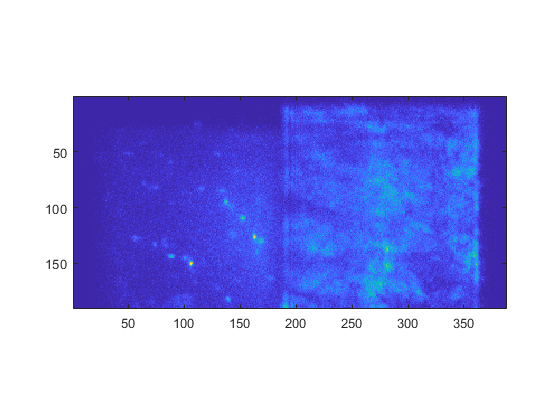

%Visualize Information
imagesc(ruler_image(:,:,1))
axis image

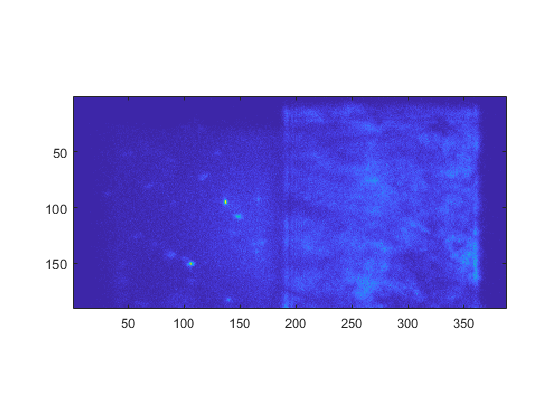

imagesc(ruler_image(:,:,2))
axis image

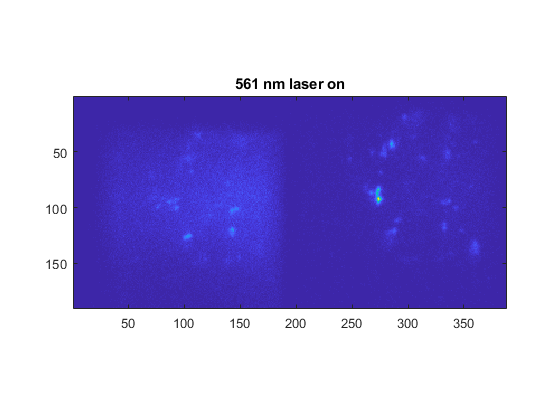


imagesc(image(:,:,1))
axis image
title('561 nm laser on')

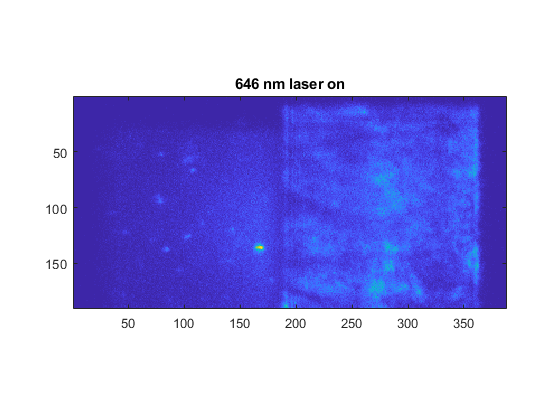

imagesc(image(:,:,2))
title('646 nm laser on')
axis image

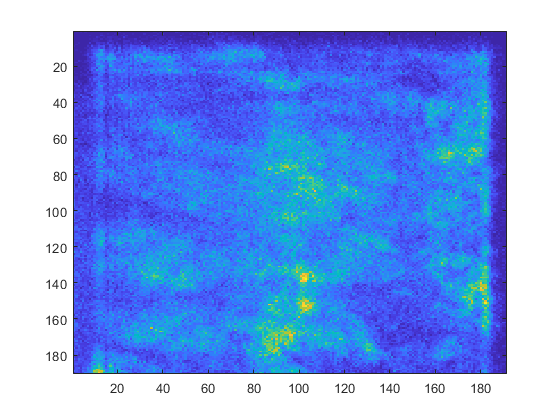


channel_split = 180; % X position split in pixels
channel_split_end = 370; % end of channel cropping
imagesc(ruler_image(:,channel_split:channel_split_end,1))

sub_ruler_image = ruler_image(:,channel_split:channel_split_end,:);

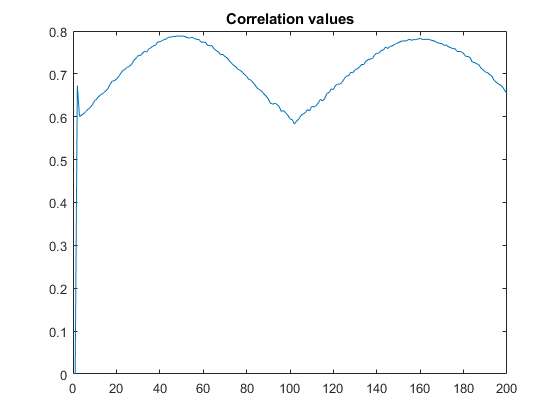

% Build ruler for subsequent measurment
[m,n,o] = size(sub_ruler_image);

C = zeros(o,1);
for i = 2:o
    C(i) = corr2(sub_ruler_image(:,:,1),sub_ruler_image(:,:,i));
end
plot(C)
title("Correlation values")

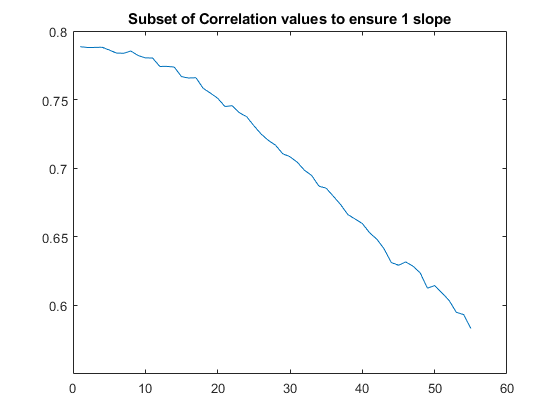

sub_C  = C(20:120);
max_corr = find(sub_C == max(sub_C));
min_corr = find(sub_C == min(sub_C));
plot(C(19+max_corr:19+min_corr));
title('Subset of Correlation values to ensure 1 slope')

ruler = sub_ruler_image(:,:,19+max_corr:19+min_corr);

% Parse image data to grab laser_sections
% Remember red channel is the even frames
laser_images = image(:,channel_split:channel_split_end,2:2:end);

indexes = get_index_from_ruler(ruler,laser_images);

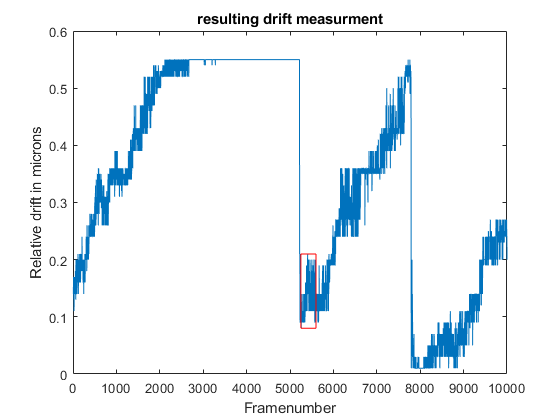

% Visualize the result
plot((1:numel(indexes))*2,indexes*0.01)
hold on
plot([5250 5600, 5600, 5250, 5250], [0.08,0.08, 0.21,0.21,0.08] ,'r')
hold off
title("resulting drift measurment")
xlabel('Framenumber')
ylabel('Relative drift in microns')

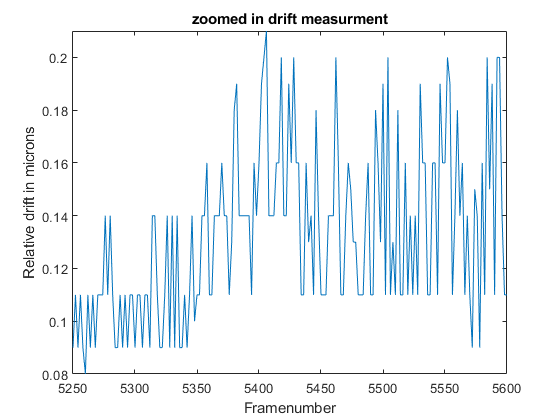


% Visualize the result
plot((1:numel(indexes))*2,indexes*0.01)
xlim([5250 5600])
ylim([0.08 0.21])
title("zoomed in drift measurment")
xlabel('Framenumber')
ylabel('Relative drift in microns')

function indexes = get_index_from_ruler(ruler, image_stack)
    [m,n,o] = size(image_stack);
    [m,n,r] = size(ruler);
    indexes = zeros(o,1);
    for i = 1:o % loop over images
        C = [];
        for j = 1:r
           C(j) = corr2(ruler(:,:,j), image_stack(:,:,i));  
        end
        indexes(i) = find(C == max(C));
    end
end